clc; clear; close all;
I = double(imread('cameraman.tif'));
[rows, cols, colors] = size(I);

## Sobel Filter

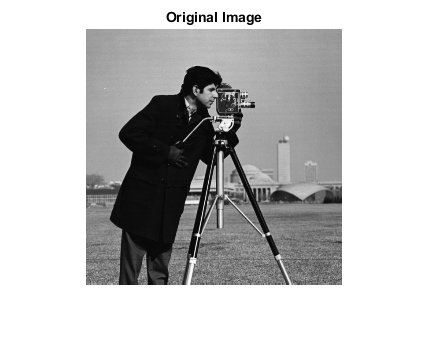

sobel = [-1 0 1; -2 0 2; -1 0 1];
sobelT = sobel';
sobel_filtered_image = zeros(rows, cols);

for i = 1:rows - 2
    for j = 1:cols - 2
        Gx = sum(sum(sobel .* I(i:i + 2, j:j + 2)));
        Gy = sum(sum(sobelT .* I(i:i + 2, j:j + 2)));
        
        sobel_filtered_image(i+1, j+1) = sqrt(Gx^2 + Gy^2);
        
    end
end

figure, imshow(uint8(I)), title('Original Image');

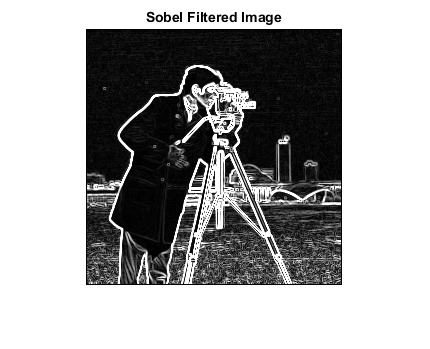

figure, imshow(uint8(sobel_filtered_image)), title('Sobel Filtered Image');

## Prewitt Filter

prewitt = [1 0 -1; 1 0 -1; 1 0 -1];
prewittT = prewitt';
prewitt_filtered_image = zeros(rows, cols);

for i = 1:rows - 2
    for j = 1:cols - 2
        Gx = sum(sum(prewitt .* I(i:i + 2, j:j + 2)));
        Gy = sum(sum(prewittT .* I(i:i + 2, j:j + 2)));
        
        prewitt_filtered_image(i+1, j+1) = sqrt(Gx^2 + Gy^2);
        
    end
end

figure, imshow(uint8(I)), title('Original Image');

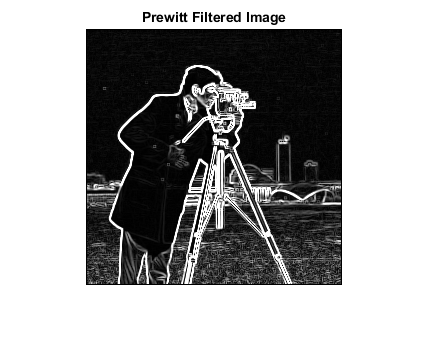

figure, imshow(uint8(prewitt_filtered_image)), title('Prewitt Filtered Image');

## Scharr Filter

scharr = [3 0 -3; 10 0 -10; 3 0 -3];
scharrT = scharr';
scharr_filtered_image = zeros(rows, cols);

for i = 1:rows - 2
    for j = 1:cols - 2
        Gx = sum(sum(scharr .* I(i:i + 2, j:j + 2)));
        Gy = sum(sum(scharrT .* I(i:i + 2, j:j + 2)));
        
        scharr_filtered_image(i+1, j+1) = sqrt(Gx^2 + Gy^2);
        
    end
end

figure, imshow(uint8(I)), title('Original Image');

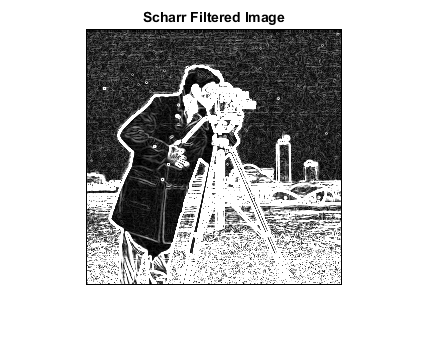

figure, imshow(uint8(scharr_filtered_image)), title('Scharr Filtered Image');